- Write a Matlab script that creates a discrete signal, x, that is a sampled cosine of length L, frequency f, sampling frequency fs.

- Create a figure with two subplots, one of which displays the signal and the other the magnitude of the fft of the signal.  Label the axes.  Test for various values of L, f and fs.  Copy and paste two screenshots of the figure here:

- Set N = 10, f = 60 Hz and fs = 200 Hz, and plot the result.  Paste screenshot of figure here:

- Create a new vector x_zero_pad of length N where N is a power of 2 and larger than N; initialize this vector to contain all zeros.  Hint: see Matlab help page for the command “zeros”

- Replace the first L values of x_zero_pad with the values of x.  Hint: Set x_zero_pad(1:3) = 10 and look at the first 10 values of x_zero_pad.

- Create a second figure, also containing two subplots that compare the magnitude of the fft of the x and the magnitude of the fft of x_zero_pad.  The horizontal axis should be in Hz.

- What is the frequency of the original signal?  What is the estimated frequency from step 3) and step 6)?  Comment on the result; support your comments with plots:

- What is the separation between points in Hz for the signal of length L and the signal of length N?  How does this affect the frequency estimation?



% inputs
N = 10000;
y = zeros(N,1) % initialize y to contain all 0's

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


s = [0; 1; 2; 3] % define the short signal, s

s =      0
     1
     2
     3




% create zero padded signal, y
y(1:length(s)) = s(1:length(s)) % assigning the first L values of y to be equal to s

y =      0
     1
     2
     3
     0
     0
     0
     0
     0
     0


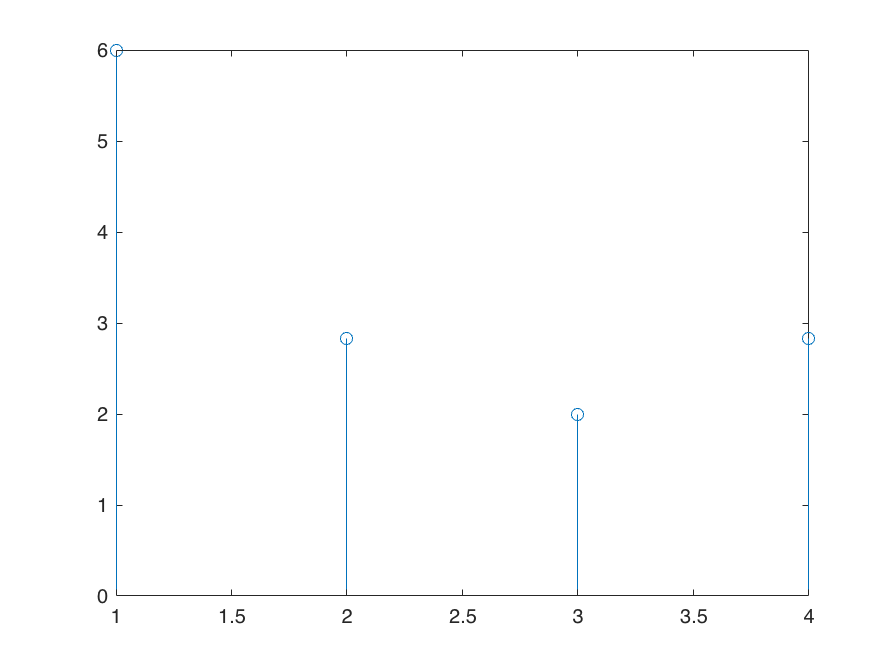



% look at DFT of short signal, s, and zero padded signal, y
S = fft(s); % computing fft
Y = fft(y);
figure(1)
stem(abs(S))

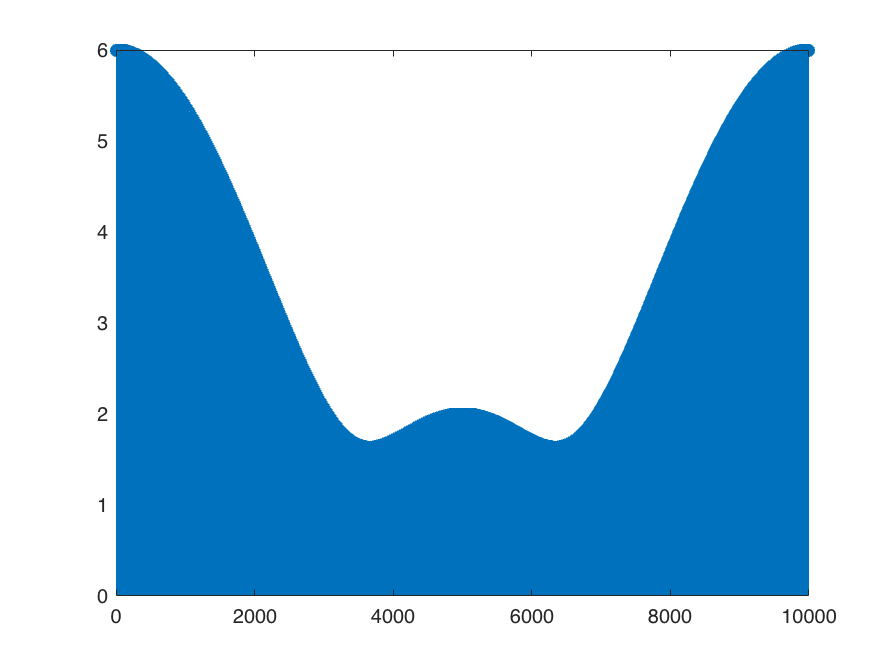

figure(2)
stem(abs(Y))


f = 100

f = 100

fs = 2

fs = 2

n = 1:3

n =      1     2     3


I = cos(2*pi*(f/fs)*n)

I =      1     1     1


%zero padded signal, y 
y(1:length(I)) = I(1:length(I))

y =      1
     1
     1
     3
     0
     0
     0
     0
     0
     0


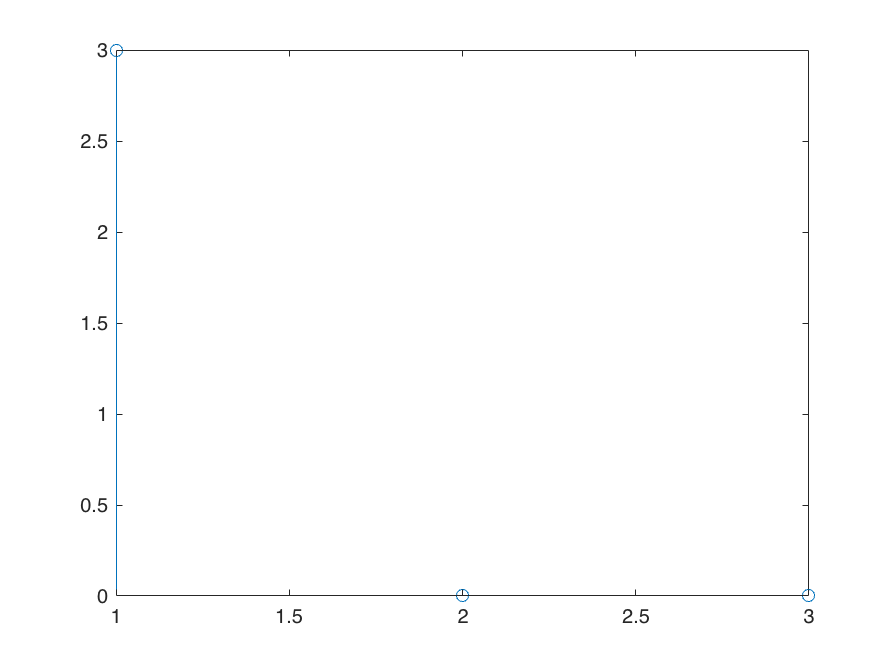


%DFT of shor signal, I, and zero padded signal, y
S = fft(I); % computing fft
Y = fft(y);
figure(1)
stem(abs(S))

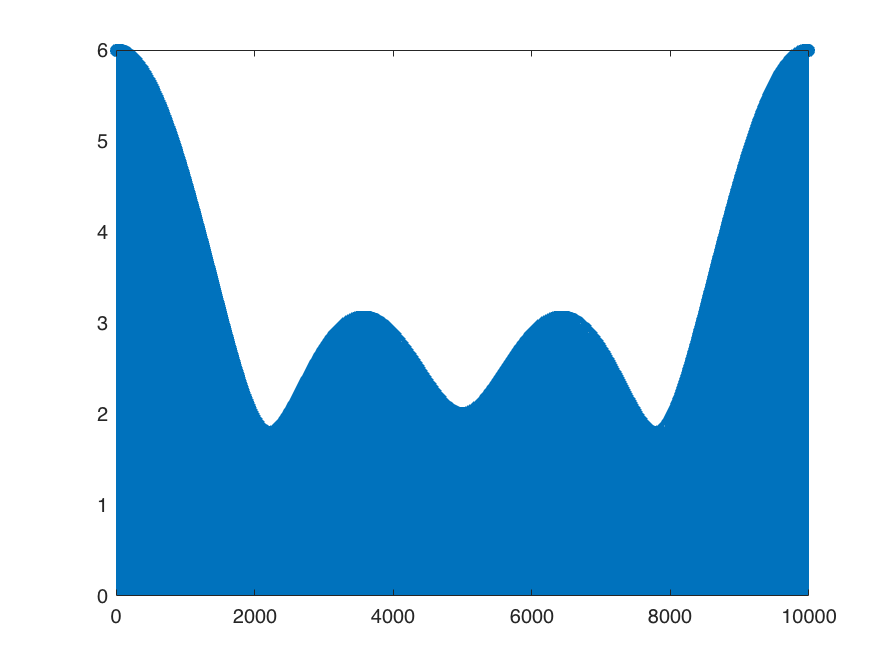

figure(2)
stem(abs(Y))

- Write a Matlab script that creates a discrete signal, x, that is a sampled cosine of length L, frequency f, sampling frequency fs.

- Create a figure with two subplots, one of which displays the signal and the other the magnitude of the fft of the signal. Label the axes. Test for various values of L, f and fs. Copy and paste two screenshots of the figure here:

- Set N = 10, f = 60 Hz and fs = 200 Hz, and plot the result.

L = 10;
n = 1:L;
f = 65.3;
fs = 200;
x = cos(2*pi*f/fs*n)

x =    -0.4624   -0.5724    0.9917   -0.3446   -0.6730    0.9670   -0.2212   -0.7624    0.9263   -0.0941


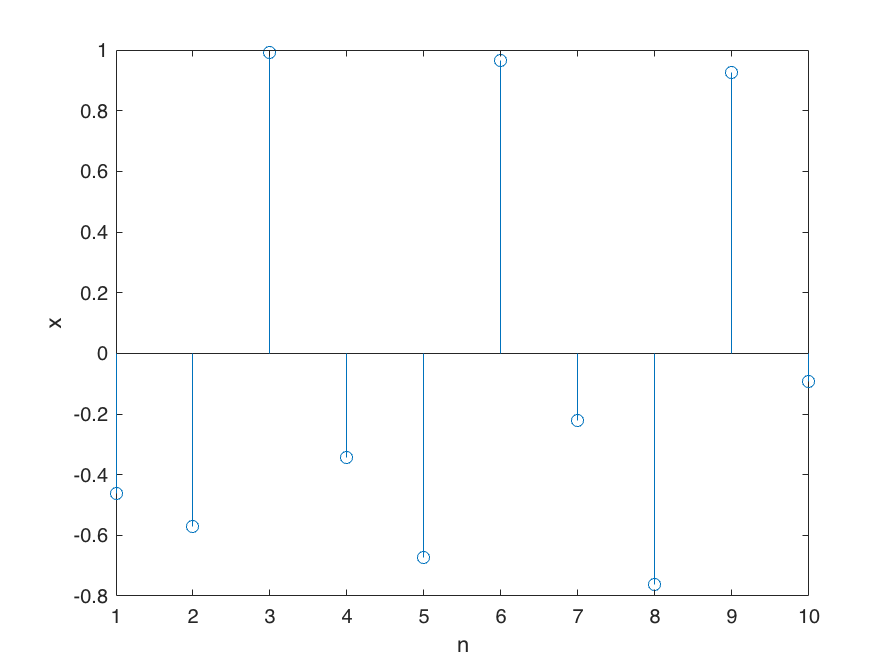

stem(x)
xlabel('n')
ylabel('x')

- Create a new vector x_zero_pad of length N where N is a power of 2 and larger than N; initialize this vector to contain all zeros. Hint: see Matlab help page for the command “zeros”

- Replace the first L values of x_zero_pad with the values of x. Hint: Set x_zero_pad(1:3) = 10 and look at the first 10 values of x_zero_pad.

N = 32;
x_zero_pad = zeros(N,1);
x_zero_pad(1:L) = x(1:L);
stem(x_zero_pad)
xlabel('n')
ylabel('x including zero padding')

- Create a second figure, also containing two subplots that compare the magnitude of the fft of the x and the magnitude of the fft of x_zero_pad. The horizontal axis should be in Hz  (still to do: convert axis to Hz!)

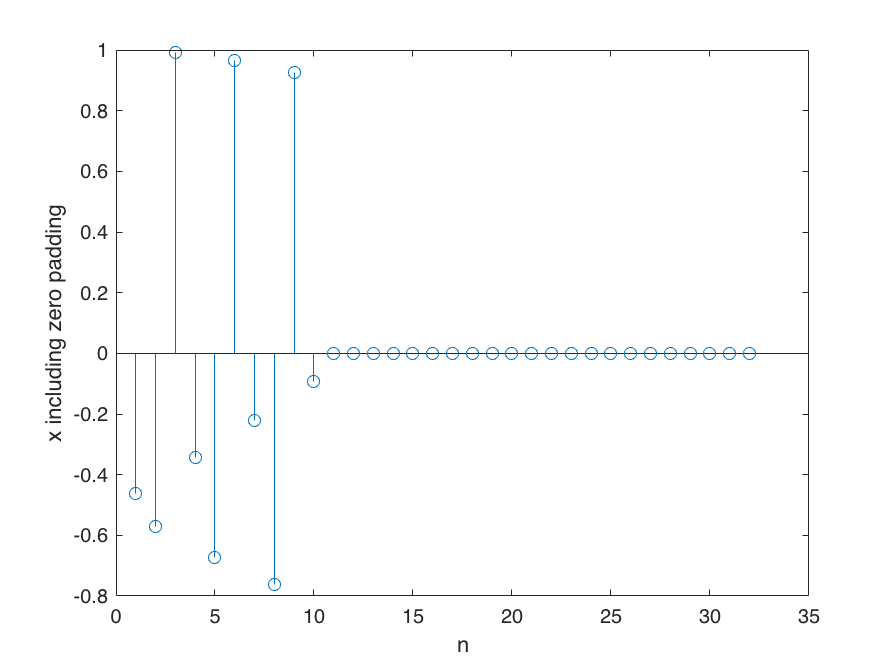

X = fft(x)
subplot(2,1,1), stem(abs(X))
xlabel('k')

ylabel('fft magn without zero padding')
X_zero_pad = fft(x_zero_pad)
subplot(2,1,2), stem(abs(X_zero_pad))
xlabel('k')


X =   -0.2452 + 0.0000i  -0.3104 + 0.0871i  -0.6337 + 0.2323i  -3.9471 + 1.1687i   2.0179 - 0.3195i   1.3680 + 0.0000i   2.0179 + 0.3195i  -3.9471 - 1.1687i  -0.6337 - 0.2323i  -0.3104 - 0.0871i


- To do: What is the frequency of the original signal? What is the estimated frequency from step 3) and step 6)? Comment on the result; support your comments with plots (

- To do: What is the separation between points in Hz for the signal of length L and the signal of length N? How does this affect the frequency estimation?

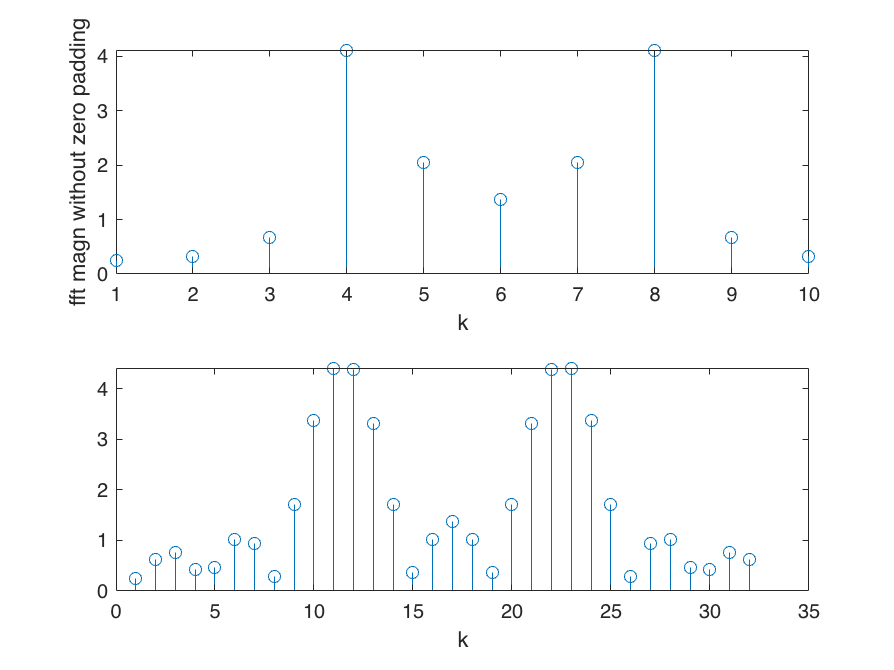

X_zero_pad =   -0.2452 + 0.0000i
  -0.5478 - 0.2863i
  -0.7704 + 0.0280i
  -0.3884 + 0.1565i
  -0.3136 - 0.3533i
  -0.9174 - 0.4355i
  -0.9258 + 0.1666i
  -0.2305 - 0.1542i
  -0.9796 - 1.4075i
  -3.3092 - 0.7047i
